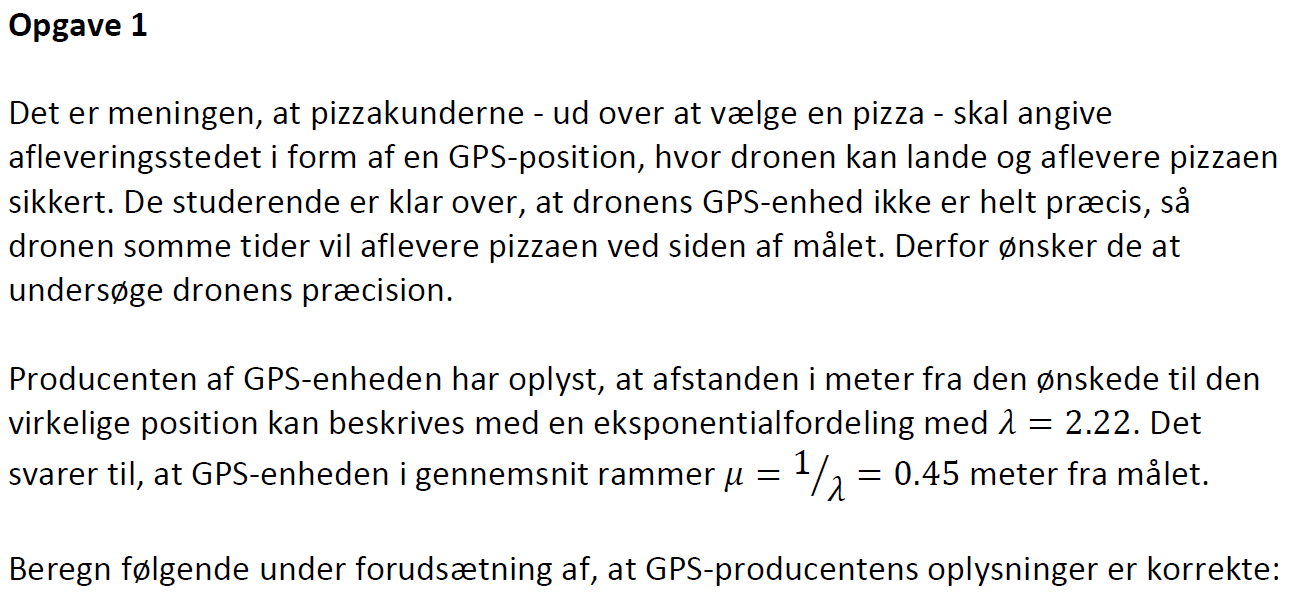

### a)

Sandsynligheden for at dronen lander indenfor en meter fra målet.

clear
lambda = 2.22; % 
mu = 1/lambda; %
y = 1; % m


 Dette er den selv udregnede version

syms x
F = lambda * exp(-lambda*x); % den comulerede
F_int = int(F,0,1);
vpa(F_int,4)

$$ans = 0.8914$$

P_1 = expcdf(y, mu)

P_1 = 0.8914


Y = linspace(0,2.5,100);
P = exppdf(Y, mu);
plot(Y, P,'DisplayName', 'Eksponentialfordelingen')
% xline(P_1)
hold on
xline(y, 'r--', DisplayName='Inden for 1 meter')
ylabel('Sandsynlighed(%)')
xlabel('Meter(m)')
legend('location', 'best')%, 'northeastoutside')
grid("minor")

y = 1

y = 1

mu = 0.45

mu = 0.4500

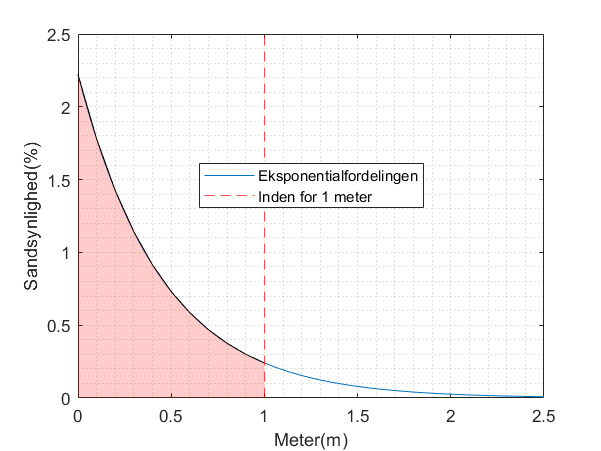

x = [0:0.1:y];
a1 = area(x,exppdf(x, mu), 'HandleVisibility','off', facecolor='r');
alpha(a1, 0.2);
hold off

### b)

Sandsynligheden for at dronen lander mellem 1 og 2 meter fra målet.

P_1_2 = expcdf(2, mu) - P_1

P_1_2 = 0.0969

### c)

Sandsynligheden for at dronen lander mere end 2 meter fra målet.